clear

Path = {    'DeepLearningData/Normal/M',...
             'DeepLearningData/Normal/T'};
         
Path2 = { 'DeepLearningData/W2/M',...
'DeepLearningData/W2/T'};

imds = imageDatastore(Path,'IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore(Path2,'IncludeSubfolders',true,'LabelSource','foldernames');

numTrainFiles = 400;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');
  



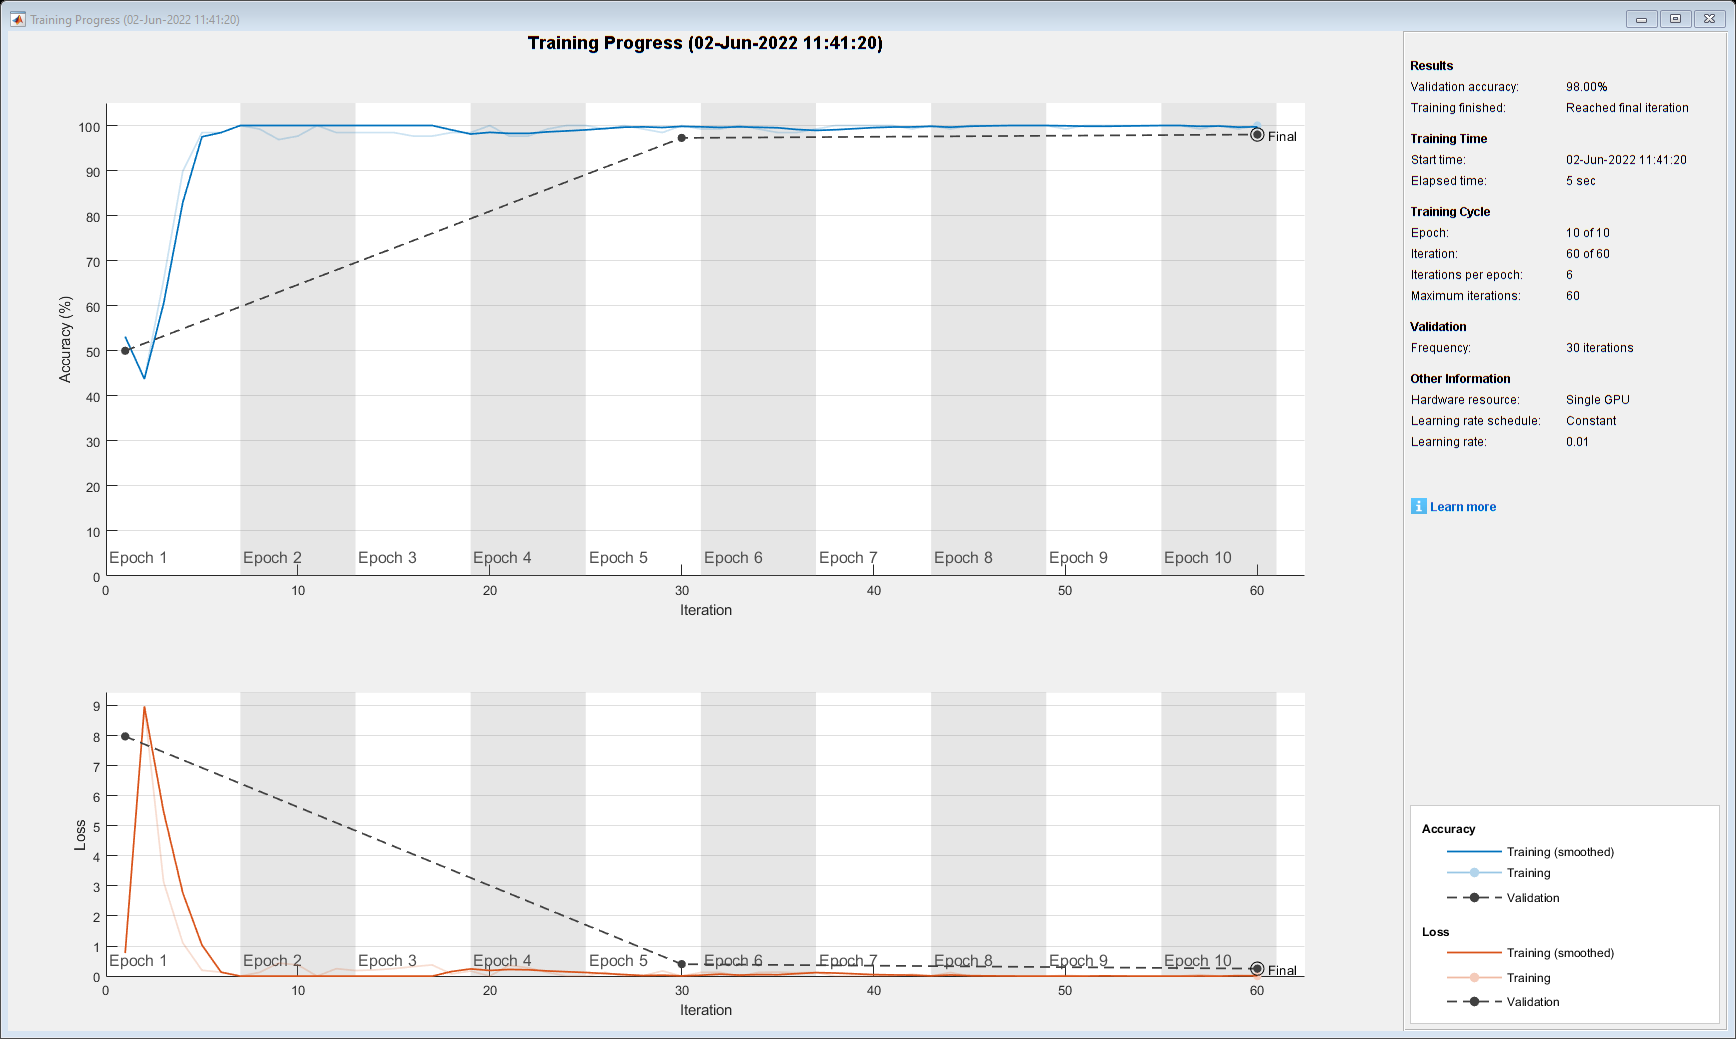

layers = [
imageInputLayer([150 150 1])
convolution2dLayer(3,8,'Padding','same')
batchNormalizationLayer
reluLayer
maxPooling2dLayer(2,'Stride',2)
convolution2dLayer(3,16,'Padding','same')
batchNormalizationLayer
reluLayer
fullyConnectedLayer(2)
softmaxLayer
classificationLayer];

net = nettrainset(imdsTrain,imdsValidation,layers);

[accuracy,~,~] = getaccontest(net,imdsTest)

accuracy = 0.9750

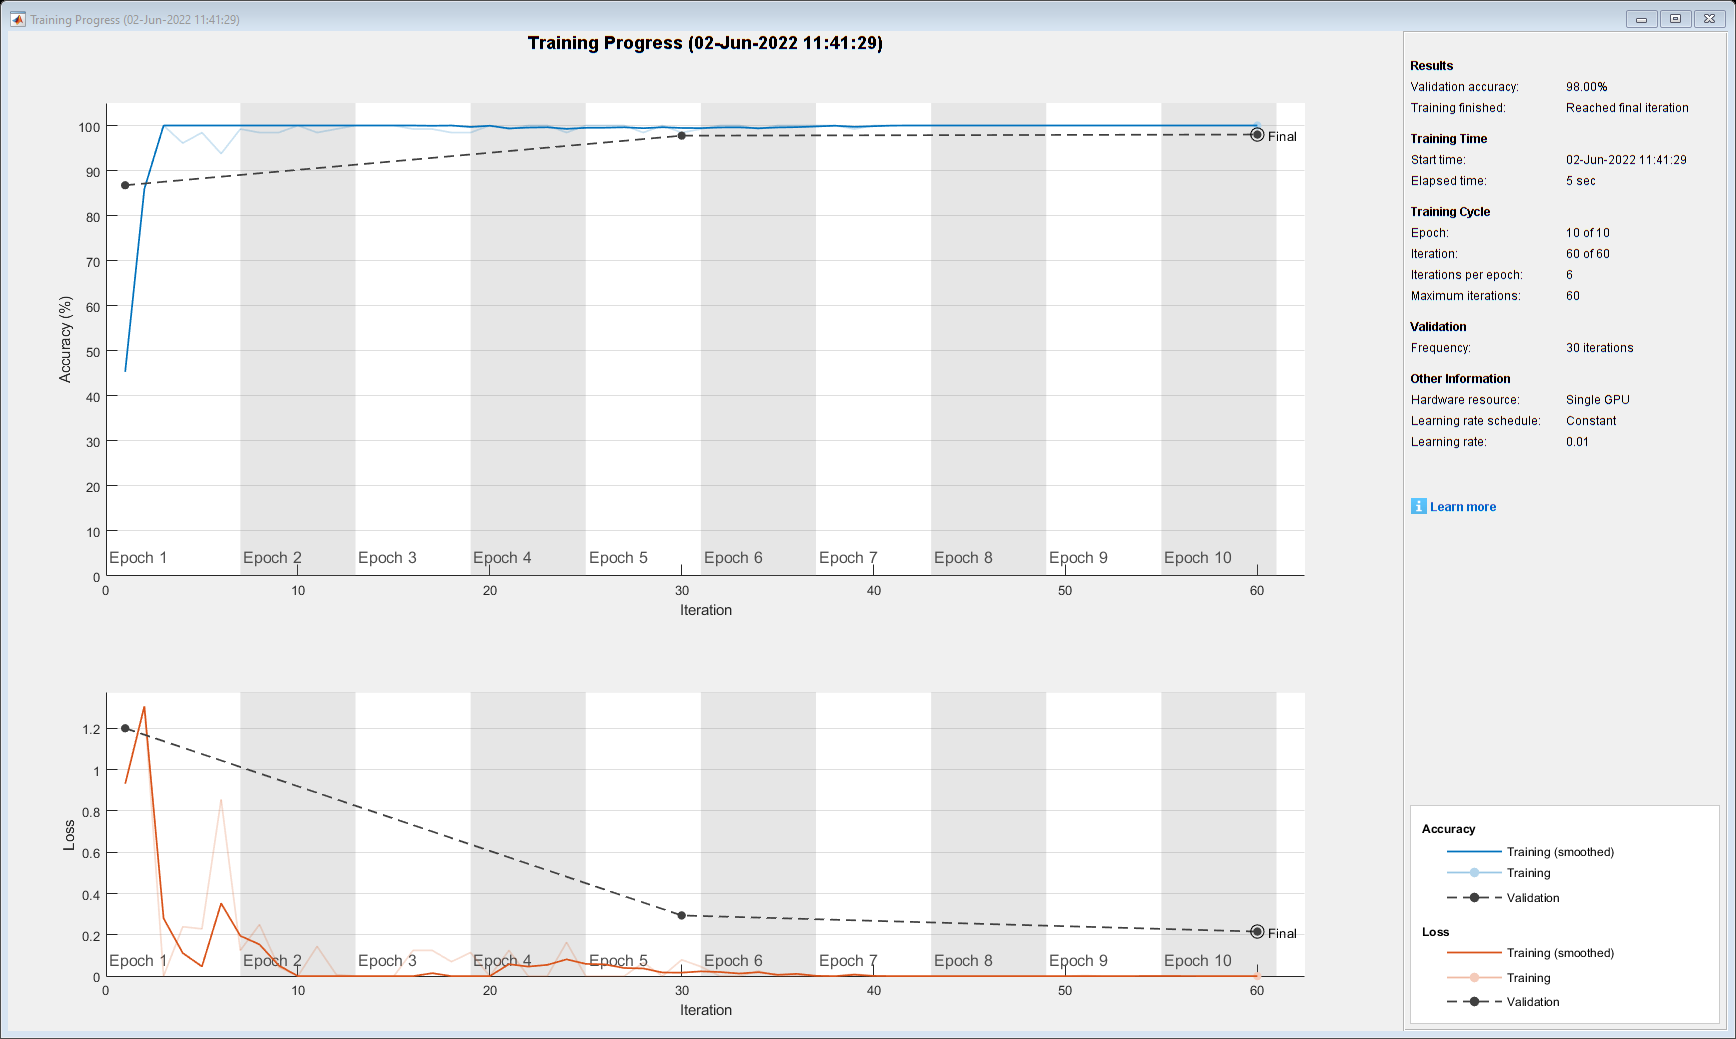

layers2 = [
imageInputLayer([150 150 1])
convolution2dLayer(3,8,'Padding','same')
batchNormalizationLayer
reluLayer
maxPooling2dLayer(2,'Stride',2)
convolution2dLayer(3,16,'Padding','same')
batchNormalizationLayer
reluLayer
maxPooling2dLayer(2,'Stride',2)
convolution2dLayer(3,16,'Padding','same')
batchNormalizationLayer
fullyConnectedLayer(10)
reluLayer
fullyConnectedLayer(2)
softmaxLayer
classificationLayer];

net2 = nettrainset(imdsTrain,imdsValidation,layers);

[accuracy2,~,~] = getaccontest(net2,imdsTest)

accuracy2 = 0.9733